# Lesson I.9:   Linear Transformations (F24)

#### Linear transformations and the action of a matrices

In general, a ***function*** $f:U\to V$ associates to every point ${\bf x}$ in the set $U$, known as the ***domain*** of the function, a point $f({\bf x})$ in the set $V$, known as the ***codomain*** of the function.   Informally, the function $f$ can be thought of as picking up the point ${\bf x}$ from $U$ and placing it down at $f({\bf x})$ in $U$.   More formally, a function must associate to every element in the domain exactly one element in $U\ldotp$  

In linear algebra, the sets $U$ and $V$ are generally sets of vectors (vector spaces) such as ${\mathbb R}^n$ and ${\mathbb R}^m$ (though the possibility of $U={\mathbb C}^n$ and $V={\mathbb C}^m$ is important for many applications).  And the focus is on ***linear functions (***aka ***linear transformations) ***defined by the property that evaluation of $f$ commutes with the formation of linear combinations.    That is,

        (I.9.1)        $f(\alpha_1{\bf x}_1+\cdots+\alpha_k{\bf x}_k)=\alpha_1 f({\bf x}_1)+\cdots+\alpha_k f({\bf x}_k)$.

Matrix-vector multiplication is an important source of linear functions.   Specifically, if $A$ is an $m\times n$ matrix, then $L:{\mathbb R}^n\to{\mathbb R}^m$ defined by

        (I.9.2)        $L({\bf x})=A{\bf x}$

is a linear transformation:

        (I.9.3)        $\matrix{
L(\alpha_1{\bf x}_1+\cdots+\alpha_k{\bf x}_k)&=&A(\alpha_1{\bf x}_1+\cdots+\alpha_k{\bf x}_k)\quad\cr 
&=&\alpha_1A{\bf x}_1+\cdots+\alpha_kA{\bf x}_k\quad\cr 
&=&\alpha_1L({\bf x}_1)+\cdots+\alpha_k L({\bf x}_k)
}$.

The linear function defined in term of a matrix $A$ by (I.9.2) is called the ***action of*** $A$.   It turns out that every linear function with domain ${\mathbb R}^n$ and codomain ${\mathbb R}^m$ is the action of some $m\times n$ matrix.   In fact, a given linear transform $L:{\mathbb R}^n\to{\mathbb R}^m$ is the action of the $m\times n$ matrix $A=[\matrix{{\bf a}_1 & {\bf a}_2 &\cdots & {\bf a}_n}]$ where

        (I.9.4)        ${\bf a}_\ell=L({\bf e}_\ell)$

and ${\bf e}_\ell$ is the $\ell^\text{th}$ column of the $n\times n$ identity matrix (the $\ell^{\text{th}}$ standard basis element).  The set of such linear functions is naturally identified with the set of $m\times n$ matrices.    In fact, it can reasonably be said that matrix-vector multiplication was invented to describe linear functions.

#### Action of matrices on images

**Making a face.** We define and list a collection of points $\{\bf f_1,\bf f_2,\dots,\bf f_N\}$in two dimensions which are the points to be marked to draw a face.    The points will be stored in a 2xN array which we will call `face. `This array will be assembled by concatenating arrays representing different parts of the face:   

- the outline (`outline`) which is a unit circle centered at the origin, 

- the left eye (`leye) `which is a circle of radius 0.1 centered at (0.4,0.4),

- the right eye` (reye) `which is a horizontal line segment from (-0.5,0.3) to (-0.5,0.3),

- the smile (`smile`) which is an arc of radius 0.5 with the origin as the center of curvature and angle (with respect to the horizonal) from 5*pi/4 to 7*pi/4.

The points are sampled rather densely from the elements.

%%%%%% Make a face
theta=0.0:0.01:2*pi; 
outline = [ cos(theta); sin(theta)];                     % outline of face 
leye    = [0.4+0.1*cos(theta);0.4+0.1*sin(theta)];       % left eye
reye    = [-0.5:0.01:-0.3; 0.4*(1+0*(-0.5:0.01:-0.3))];  % right eye
theta   = 5*pi/4:0.01:7*pi/4;
smile   = [0.5*cos(theta); 0.5*sin(theta)];              % smile
face    = [outline leye reye smile];                     % face assembled

**Draw a face.**    The MATLAB `plot `command is used to place images on the computer screen.   Here we use the plot command to mark, with a dot, each of the points in our list.    The `axis equal `command is intended to assure that the vertical and horizontal distances on the screen have the same scale.

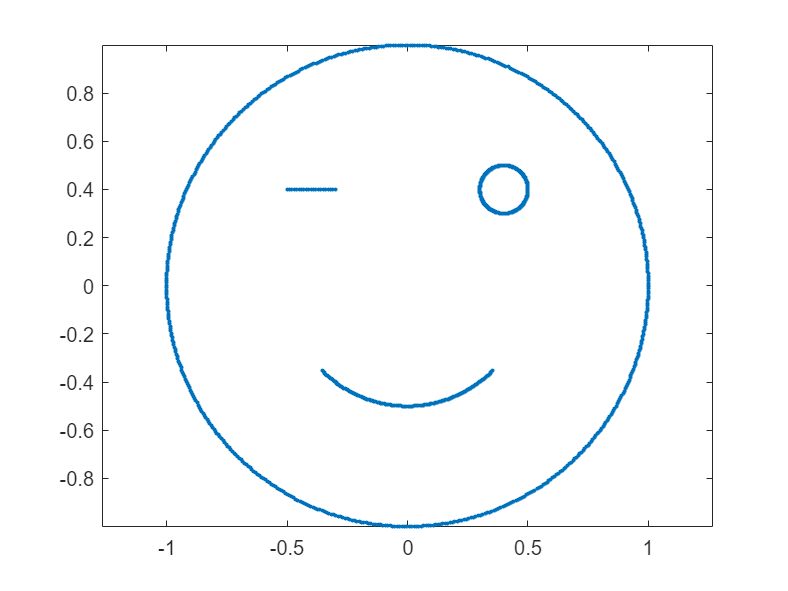

%%%%%% Plot a face
plot(face(1,:),face(2,:),'.')
axis equal

**Exploring linear functions.**   Consider the linear function $T({\bf x})=\left[\matrix{1&1\cr2 &1}\right]{\bf x}$.   We visualize this function by plotting the face and the image of the face, the set of points $\{T({\bf f}_1),\dots,T({\bf f}_N)\}$, next to each other.    We have put the plotting code into a function `seelinear` which can be found at the end of this file.

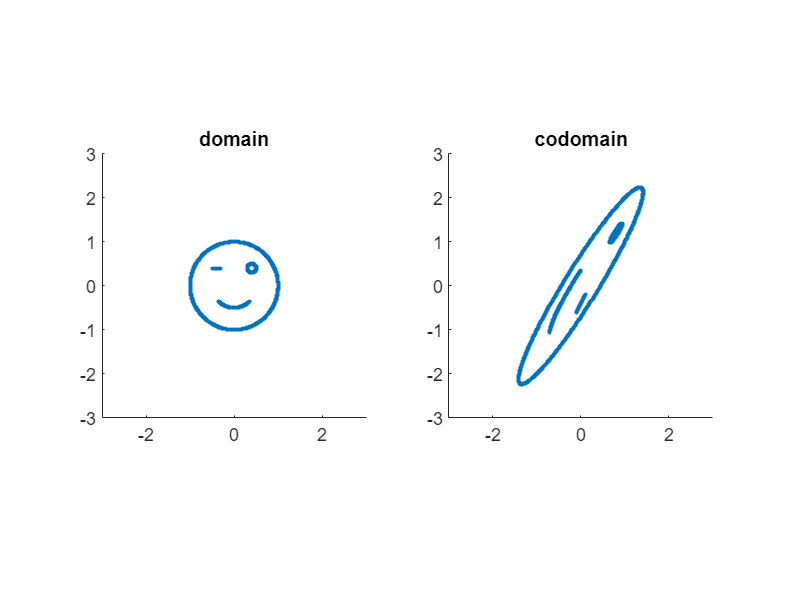

A=[1 1; 2 1];
seelinear(A,face)

We see that the face is distorted and reoriented.   Interestingly, the left and right eyes seem to have switched places (more on that in later lessons).  

**Dilation and constriction.  **Consider $T({\bf x})=\left[\matrix{1 & 0 \cr 0 & 1 }\right]{\bf x}$.   Visualizing this mapping reveals unsurprisingly that the identity map changes nothing.

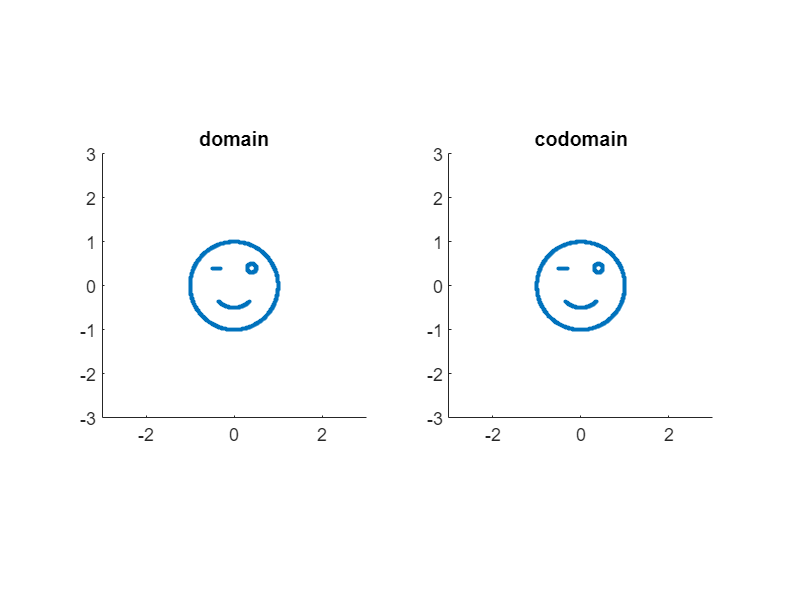

figure
A=[1 0; 0 1];
seelinear(A,face)

Suppose we multiply the matrix for the previous linear map by 2.   Consider $T({\bf x})=\left[\matrix{2 & 0 \cr 0 & 2 }\right]{\bf x}$.   Visualizing this mapping reveals that it enlarges everything and distorts nothing (the image of the circular face is a circular face).   

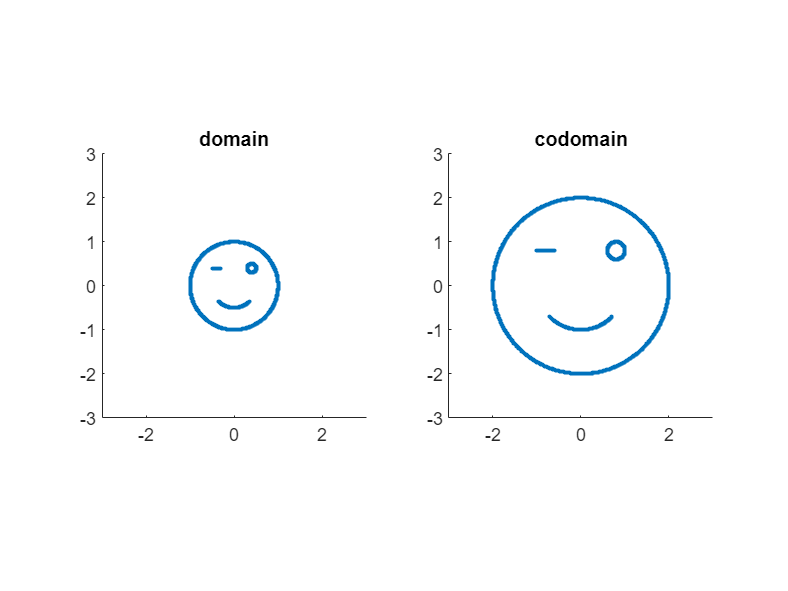

figure
A=[2 0; 0 2];
seelinear(A,face)

Consider $T({\bf x})=\left[\matrix{\frac12 & 0 \cr 0 & \frac12 }\right]{\bf x}$.   Visualizing this mapping reveals that it constricts everything and again distorts nothing (the image of the circular face is a circular face).   

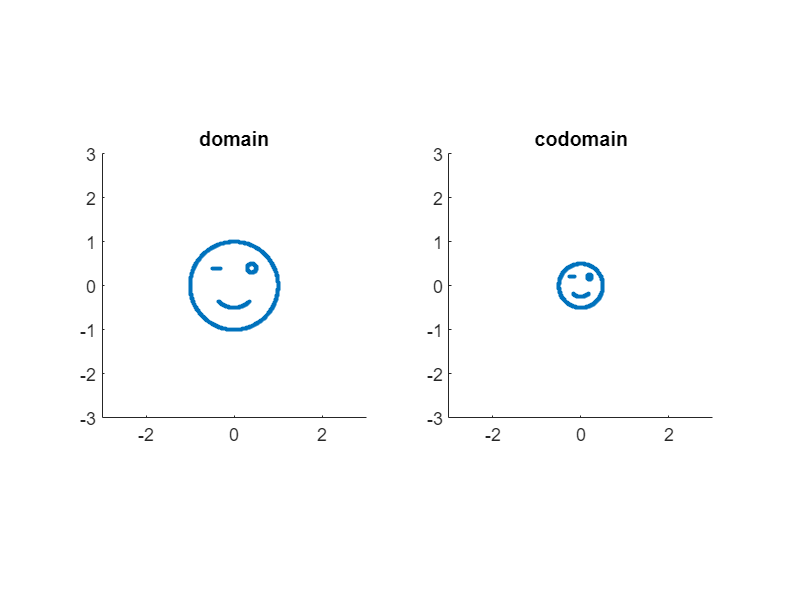

figure
A=[1/2 0; 0 1/2];
seelinear(A,face)

**Inhomogeneous dilation.   **A linear mapping may stretch by different amounts in different directions.   Consider 

                $T({\bf x})=\left[\matrix{2 & 0 \cr 0 & \frac34 }\right]{\bf x}$.   

The first coordinate is doubled but the second constricted resulting in a shorter, wider image.

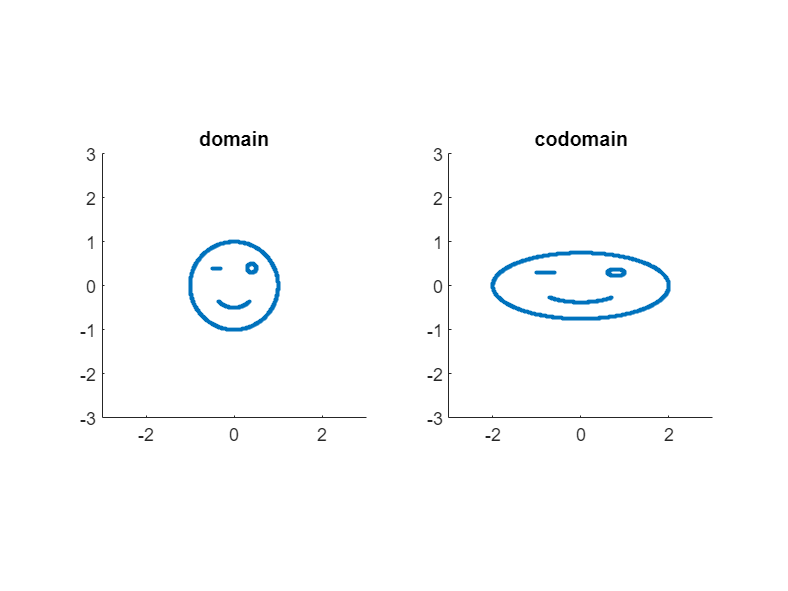

figure
A=[2 0; 0 3/4];
seelinear(A,face)

Consider the nondiagonal but symmetric standard matrix $A=\left[\matrix{2&1\cr1&1}\right]$.

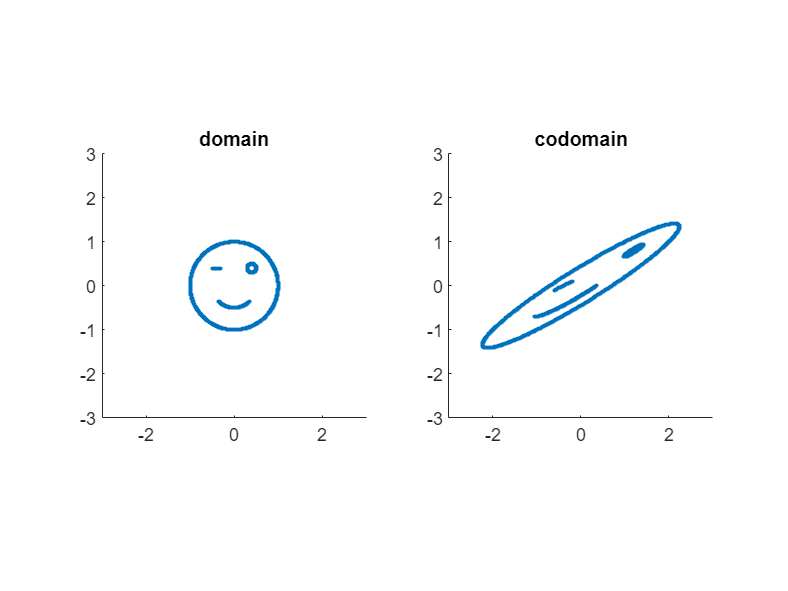

figure
A=[2 1; 1 1];
seelinear(A,face)

Again the image is stretched out in one direction and squished in a perpendicular direction, but for this linear transformation the stretching and the squishing are not aligned with the coordinate axes.  The directions of stretching or squishing, the ***singular*** ***directions***, play a significant role in the singular value decomposition enumerated towards the end of the course.

Consider a nonsymmetric standard matrix such as $A=\left[\matrix{1&1\cr0&1}\right]$.

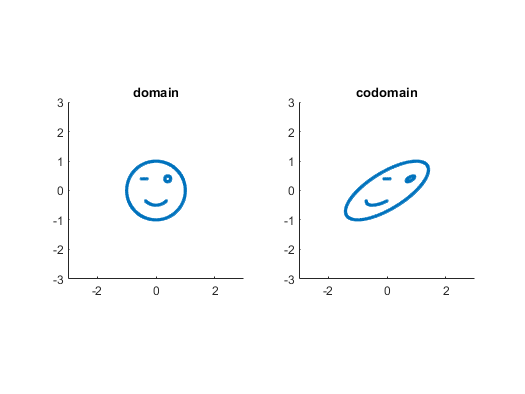

figure
A=[1 1; 0 1];
seelinear(A,face)

Note that in all of the cases above, the image of the circular face is an ellipse.    This is true for all linear transformations, but the ellipse may be degenerate (i.e., having an axis of length zero).   

**Rotation matrices.**    The matrix $\text{Rot}(\theta)=\left[\matrix{\cos\theta & -\sin\theta \cr \sin\theta & \cos\theta}\right]$is the standard matrix for a linear transformation producing counterclockwise rotation through an angle $\theta$.   For example, consider $A=\text{Rot}(\pi/4)=\left[\matrix{\frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2}\cr \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2}}\right]$.   

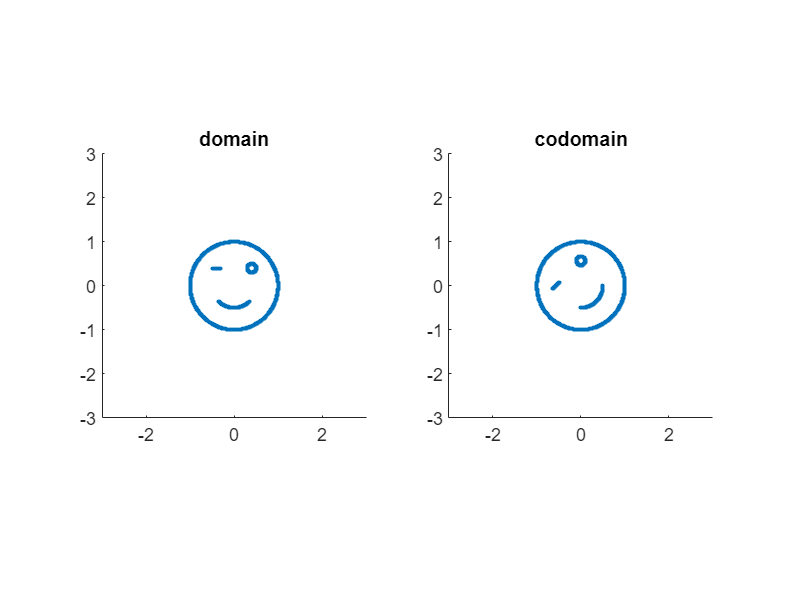

figure
A=[cos(pi/4) -sin(pi/4); sin(pi/4) cos(pi/4)];
seelinear(A,face)

If we continuously vary the angle of rotation and quickly replot the figure we can animate a rotating face.

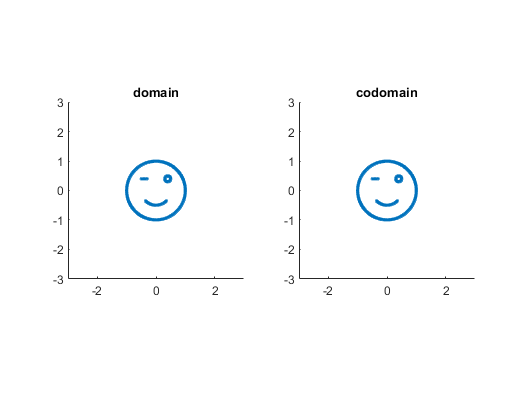

figure
for theta=0:pi/20:4*pi
    A=[ cos(theta) -sin(theta); sin(theta) cos(theta)];
    clf     % clears the previously drawn figures
    seelinear(A,face)
    pause(0.1)    % displays the image and paused briefly
end

If we multiply a rotation by a real scalar, we combine the effects of dilation and rotation, e.g., $A=\left[\matrix{2 & -2\cr 2 & 2}\right]$

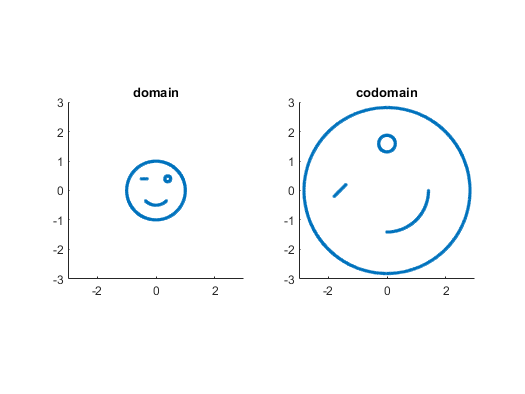

figure
A=[2 -2; 2 2];
seelinear(A,face)

**Stretch and turn vs. turn and stretch.   **Consider $A=\left[\matrix{\frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2}\cr \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2}}\right]
\left[\matrix{2&0\cr0&1}\right]=
\left[\matrix{\sqrt{2} & -\frac{\sqrt{2}}{2}\cr \sqrt{2} & \frac{\sqrt{2}}{2}}\right]$.

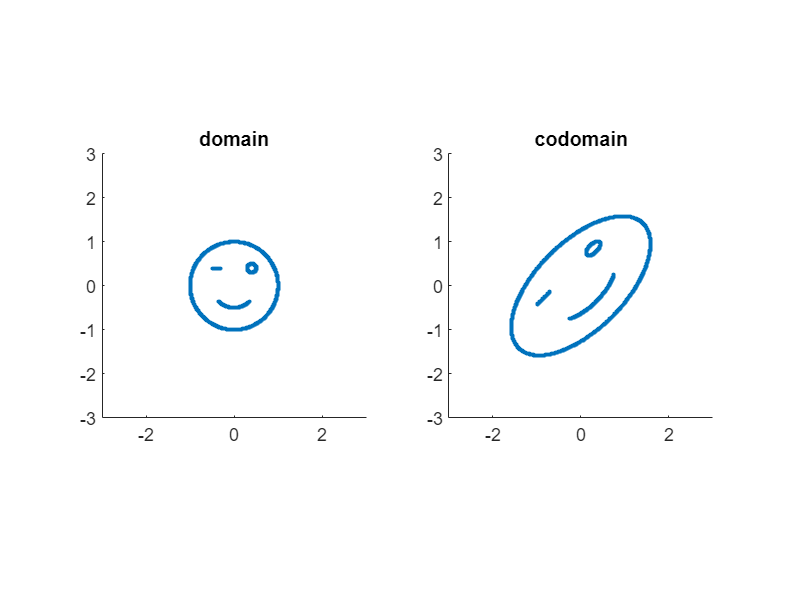

figure
A=[sqrt(2) -sqrt(2)/2; sqrt(2) sqrt(2)/2];
seelinear(A,face)

Compare with $A=\left[\matrix{2&0\cr0&1}\right]\left[\matrix{\frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2}\cr \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2}}\right]
=
\left[\matrix{\sqrt{2} & -\sqrt{2}\cr \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2}}\right]$.

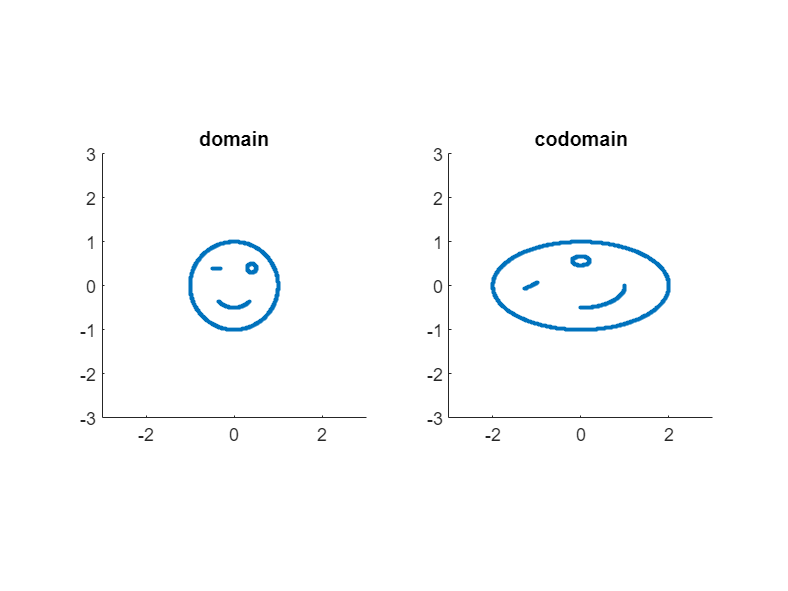

figure
A=[sqrt(2) -sqrt(2); sqrt(2)/2 sqrt(2)/2];
seelinear(A,face)

For composition of linear transformations, as for matrix multiplication, order matters.

**Reflection.   **The matrix $\text{Ref}(\theta)=\left[\matrix{\cos2\theta & \sin2\theta\cr \sin2\theta & -\cos2\theta}\right]$reflects through the line through the origin making an angle of $\theta$ with the $x-$axis.  Notice that the determinant of a reflection matrix is -1.

   Consider $A=\text{Ref}(\pi/4)=\left[\matrix{0 & 1\cr 1 & 0}\right]$.

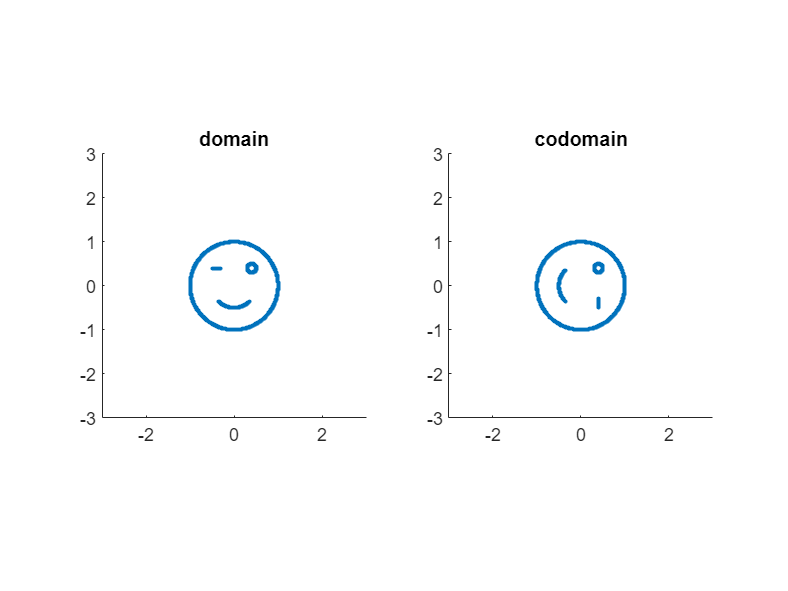

figure
A=[0 1; 1 0];
seelinear(A,face)

Almost looks like a rotation, but notice the eyes.

**Preservation of affine structure.   **Consider the image of a grid instead of a face.

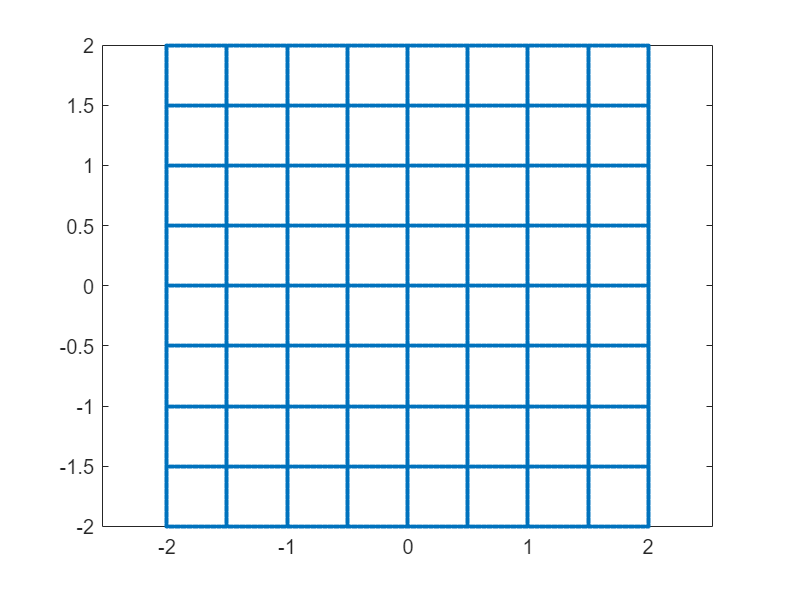

s =-2:0.01:2;      % row vector with entries ranging from -2 to 2
c = 0.0*s+1;     % row vector of all ones with the same length as s 
hlines = [[s; 2*c] [s; 1.5*c] [s; c] [s; 0.5*c] [s; 0*c] [s; -2*c] [s; -1.5*c] [s; -c] [s; -0.5*c]];
vlines = hlines([2 1],:);
grid = [hlines vlines];
%%%%%% Plot the grid
figure
plot(grid(1,:),grid(2,:),'.')
axis equal

For a linear transformation there is a notable property that the image of each line is a line.

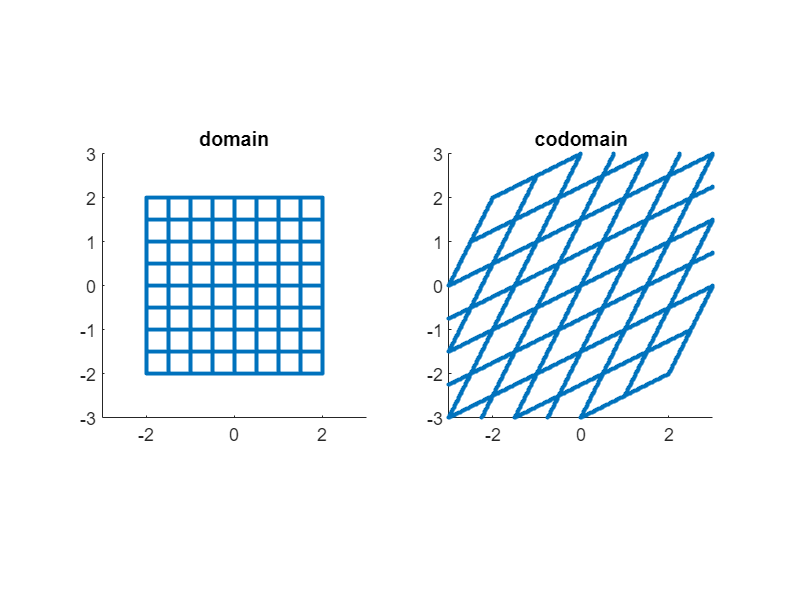

figure
seelinear([2 1;1 2],grid)

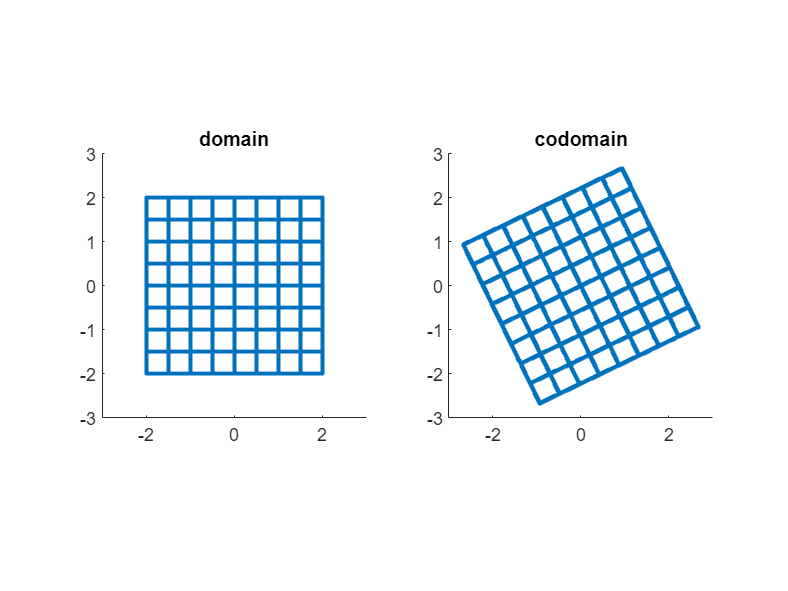

figure
seelinear([cos(pi/7) -sin(pi/7); sin(pi/7) cos(pi/7)],grid)

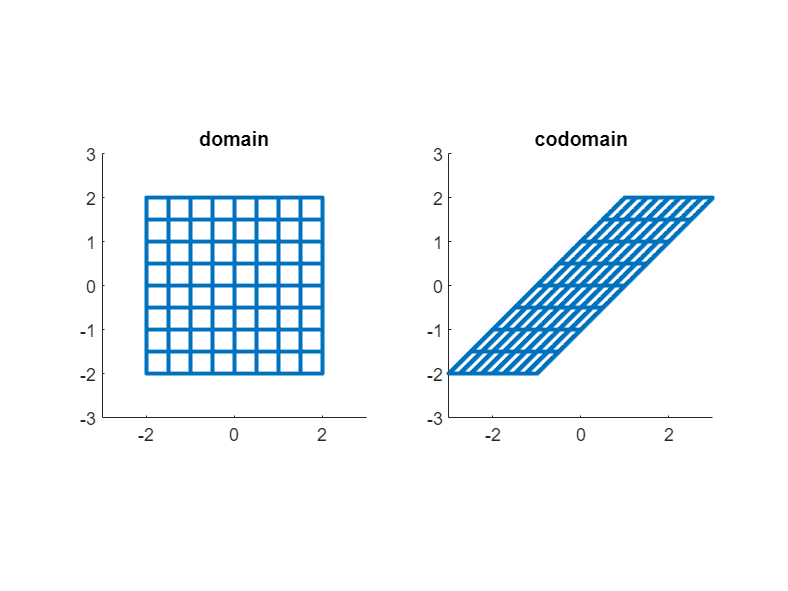

figure
seelinear([0.5 1; 0 1],grid)

A very basic property of linear transformations is that they preserve affine structures; i.e., the image of an affine set (such as a point, a line, a plane,...) is always an affine set.   A function that preserves affine structure is called an *affine transformation*.   A linear transformation is a special affine transformation with the additional property that the image of the zero vector ${\bf 0}$ in the domain is always the zero vector ${\bf 0}$ in the codomain; i.e., $L({\bf 0})={\bf 0}$.

**Getting ahead.   **

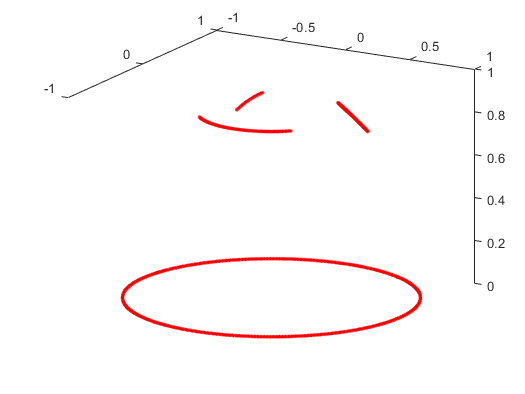

theta=0.0:0.01:2*pi; 
outline3d = [ cos(theta); sin(theta); 0*theta];                     % outline of face 
leye3d      = [0.4+0.1*cos(theta);0.4+0.1*sin(theta); sqrt(1- (0.4+0.1*cos(theta)).^2-(0.4+0.1*sin(theta)).^2) ];       % left eye
reye3d    = [-0.5:0.01:-0.3; 0.4*(1+0*(-0.5:0.01:-0.3)); sqrt(1- (-0.5:0.01:-0.3).^2-(0.4*(1+0*(-0.5:0.01:-0.3))).^2)];  % right eye
theta   = 5*pi/4:0.01:7*pi/4;
smile3d   = [0.5*cos(theta); 0.5*sin(theta); sqrt(1- (0.5*cos(theta)).^2-(0.5*sin(theta)).^2)];                   
head      = [outline3d leye3d reye3d smile3d];
figure 
plot3(head(1,:),head(2,:),head(3,:),'.r')
view(2)
for n=1:70
    view(3*n,90+n)
    pause(0.25)
end

**Inverse transforms.    **For a function $f:U\to V$,  the function $g:V\to U$ is the ***inverse function*** of $f$ (typically denoted $f^{-1}$) if and only if

                (I.9.5a)        $g(f({\bf x}))={\bf x}\qquad\text{for every}\quad  {\bf x}\in U$    

and    

                (I.9.5b)        $f(g({\bf y}))={\bf y}\qquad\text{for every}\quad  {\bf y}\in V$.

Informally, we can say that $f$ and $g$ undo each other.

Not every function has a inverse function.   There are two ways that a function may fail to have an inverse.   

- There may be distinct points in the domain, say ${\bf x}_1$ and ${\bf x}_2$, that have the same image ${\bf y}$ in the codomain (i.e., $f({\bf x}_1)=f({\bf x}_2)={\bf y}$).   In this situation (many-to-one), (I.9.5a) cannot be fulfilled because it requires $g(f({\bf x}_1))={\bf x}_1$ and $g(f({\bf x}_2))={\bf x}_2$ but because $f({\bf x}_1)=f({\bf x}_2)={\bf y}$ that means$g({\bf y})={\bf x}_1$ and $g({\bf y})={\bf x}_2$ which is impossible as to be a function $g$ must have only one value at each point in the domain.

- There may be a point in the codomain, say ${\bf y}$, for which there is no point ${\bf x}$ in the domain such that $f({\bf x})={\bf y}$.   In this situation (none-to-one), (I.9,5b) cannot be fulfilled as there is no point making $f$ equal to ${\bf y}$.

If every point in the codomain is the image of exactly one point in domain, then the function has an inverse function.   In this situation (one-to-one), both (I.9.5a) and (I.9.5b) will be fulfilled.   That is, a function has an inverse function if and only if it defines a one-to-one correspondence between the domain and the codomain.    

For a linear transformation that is the action of an $m\times n$ matrix $A$, there is a inverse transformation if and only if the linear system $A{\bf x}={\bf y}$ has a unique solution for every vector ${\bf y}$ in the codomain.   That occurs, if and only if every row and column of $A$ has a pivot.    Every row of the coefficient matrix having a pivot guarantees that the last column of the augmented matrix has no pivot (i.e., the solution exists).    Every column having a pivot guarantees that there is no free variable (i.e., the solution is unique).   Every row and column of the coefficient having a pivot matrix is exactly the condition for the matrix $A$ to have an inverse matrix.  

**A linear transform failing both conditions for existence of an inverse**


$$A=\left[\matrix{1& 2\cr 1/2& 1}\right]$$
          
$$\text{rref}(A)=\left[\matrix {1 & 2 \cr 0 & 0 }\right]$$
      

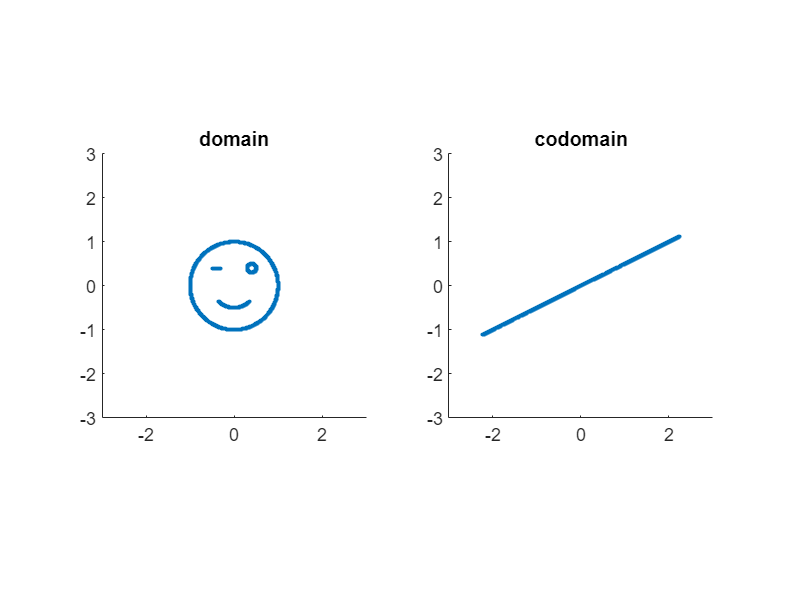

figure
seelinear([1 2; 1/2 1],face)

 When all rows and columns of the coefficient matrix have pivots, the linear transform $T({\bf x})=A{\bf x}$ has a inverse transform given by the inverse matrix:

                (I.9.6)        $T^{-1}({\bf y})~=~A^{-1}{\bf y}.$

That is, the inverse action of a matrix is the action of the inverse matrix.    It can be said that inverse matrices were invented to represent the inverse of linear transformations.

**Follow-up problems****.**

**Problem I.9.1:  **Determine which of the following transformations are linear.

    (a)    $T(x,y,z)=\left[\matrix{x +y \cr y+z \cr x-z}\right]$        (b)    $T(x,y,z)=\left[\matrix{x \cr 1 \cr z}\right]$        (c)    $T(x,y,z)=\left[\matrix{x+y \cr x-y \cr z^2}\right]$

**Problem I.9.2:  ** Explain why if $L$ is a linear transformation, then $L({\bf 0})={\bf 0}$.

**Problem I.9.3:  **Describe the linear map having the standard matrix $A=\left[\matrix{\cos^2\theta & \cos\theta\sin\theta\cr\cos\theta\sin\theta & \sin^2\theta}\right]$.

**Problem I.9.4:  **What is the matrix for the linear transform defined in Problem I.9.1 (a)?

**Problem I.9.5:   **Show that the product of rotation matrices is a rotation matrix.

**Problem I.9.6:   **Show that $2\times 2$ rotation matrices commute.

**Problem I.9.7:**   Show that the product of two reflection matrices is a rotation matrix.

**Problem I.9.8:  **Suppose that $T:{\mathbb R}^3\to{\mathbb R}^5$ is it possible that the inverse $T^{-1}$ exists?

**Problem I.9.9:  **Suppose that $T:{\mathbb R}^5\to{\mathbb R}^3$ is it possible that the inverse $T^{-1}$ exists?

**Problem I.9.10:  **Suppose that $T:{\mathbb R}^5\to{\mathbb R}^5$ is defined by  $T({\bf x})={\bf 0}\qquad\text{for}\quad {\bf x}\in{\mathbb R}^5.$   Show that $T$ is linear.   Does $T$ have an inverse?

**Appendix I.9.A:   MATLAB code**

function seelinear(A,face)
    subplot(1,2,1)       % plot on first (left) panel of two in a row
    hold on
    title('domain')
    plot(face(1,:),face(2,:),'.')
    axis([-3 3 -3 3])
    axis square
    Aface=A*face;        % transform the points composing face
    subplot(1,2,2)       % plot on second (right) panel of two in a row
    hold on
    title('codomain')
    plot(Aface(1,:),Aface(2,:),'.')
    axis([-3 3 -3 3])
    axis square
end
